clc, clear, close all
rng(1);           
run('definitions.m');

VLP definitions and parameters loaded successfully


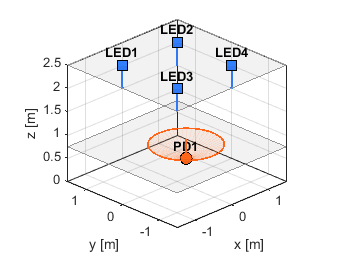


mode = 'multi_fixed_LED';
AP = AP_config.(mode);
run('fig_setup.m')


Nsamples = 1000;     % muestras por posición y por AP
S_min = 1e-12 ; % evitar potencias negativas

% Ground truth positions
xv = testbed.x(1):testbed.gridstep:testbed.x(2);
yv = testbed.y(1):testbed.gridstep:testbed.y(2);
[X, Y] = meshgrid(xv, yv);

Npos = numel(X);
nAP  = numel(AP);
S_r = cell(Npos, nAP);
SNR = cell(Npos, nAP);

for i_pos = 1:Npos
    UE.pos(1:2) = [X(i_pos), Y(i_pos)];
    UE.n_r = -angles2vec([randi(UE.delta_tilt+1)-1, randi(360)]); % error:PD tilt

    for i = 1:nAP
        h0 = h_LOS(AP(i), UE, channel.model);
        S_0 = UE.R_pd * AP(i).P_t * h0; % without w_noise
        w_noise  = sqrt(channel.sigma2) * randn(1, Nsamples);
        S_samples = S_0 + w_noise;
        S_samples = max(S_samples, S_min); % [Amp]
        S_r{i_pos, i} = S_samples;
        SNR{i_pos, i} = 10*log10( S_0^2 / channel.sigma2); % (R_pd*P_r)^2/sigma^2
    end
end

SNR_mean_AP1 = mean(cellfun(@(x) mean(x), SNR(:,1)));
fprintf('SNR mean AP1 %.1f dB', SNR_mean_AP1);

SNR mean AP1 16.9 dB

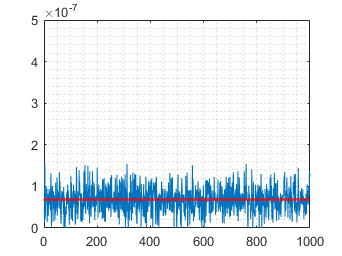


figure
plot(S_0 + w_noise)
yline(S_0,'r','LineWidth',2)
yaxis([0 5e-7])
grid minor

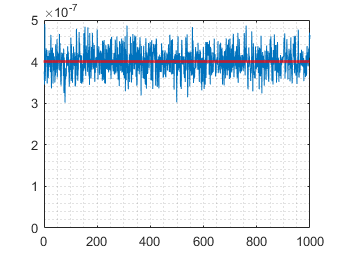


S_r_max = 4e-7;
figure
plot(S_r_max + w_noise)
yline(S_r_max,'r','LineWidth',2)
yaxis([0 5e-7])
grid minor

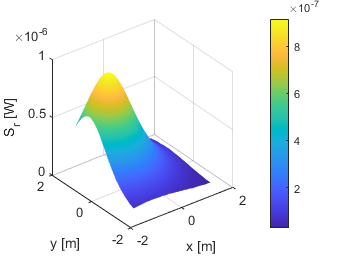


figure
S_r_mean_AP1 = cellfun(@(x) mean(x), S_r(:,1));
surf(X, Y, reshape(S_r_mean_AP1, size(X)));
xlabel('x [m]'); ylabel('y [m]'); zlabel('S_r [W]');
shading interp; colorbar;

**Obtaining the mean**

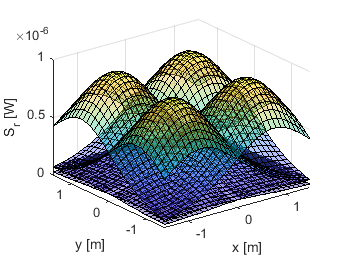

S_r_mean = zeros(Npos, nAP);
for i=1:nAP
    S_r_mean(:, i) = cellfun(@(x) mean(x), S_r(:,i));
end

figure
surf(X, Y, reshape(S_r_mean(:,1), size(X)),FaceAlpha=0.4);
hold on
surf(X, Y, reshape(S_r_mean(:,2), size(X)),FaceAlpha=0.4);
surf(X, Y, reshape(S_r_mean(:,3), size(X)),FaceAlpha=0.4);
surf(X, Y, reshape(S_r_mean(:,4), size(X)),FaceAlpha=0.4);
xlabel('x [m]'); ylabel('y [m]'); zlabel('S_r [W]');
%shading interp; %colorbar;
xlim([testbed.x(1) testbed.x(2)])
ylim([testbed.y(1) testbed.y(2)])
zlim([0 10e-7])

**Estimación por trilaterizacion**

est_pos = zeros(Npos, 2);   % (x_est, y_est)
true_pos = [X(:), Y(:)];
d_est_all = zeros(Npos, nAP);

for ip = 1:Npos
    % Medición media para esta posición (nAP x 1)
    S_r_i = S_r_mean(ip, :).';
    
    % --- Estimar distancia por inversa del modelo LOS ---
    d_i = zeros(nAP,1);
    for i = 1:nAP
        h_vert = AP(i).pos(3)-UE.pos(3);
        d_i(i) = ( UE.R_pd * ((AP(i).m+1)/(2*pi)) * UE.A_det*...
                      UE.Ts * UE.g_ri * (h_vert^(AP(i).m+1))*...
                       (AP(i).P_t)/S_r_i(i)) ^ (1/(AP(i).m+3));
    end
    d_est_all(ip,:) = d_i;

    % --- Resuelve posición (x,y) por mínimos cuadrados ---
    % Ecuaciones: (x - xi)^2 + (y - yi)^2 = di^2
    A = []; b = [];
    ref = 1;  % toma AP1 como referencia
    x1 = AP(ref).pos(1); y1 = AP(ref).pos(2);
    for ia = 2:nAP
        xi = AP(ia).pos(1); yi = AP(ia).pos(2);
        A = [A; 2*(xi - x1), 2*(yi - y1)];
        r1 = sqrt(d_i(ref)^2 - h_vert^2);
        ri = sqrt(d_i(ia)^2  - h_vert^2);
        b = [b; (r1^2 - ri^2) + (xi^2 + yi^2) - (x1^2 + y1^2) ];
    end
    
    if rank(A) == 2
        pos_est = A\b;
        est_pos(ip,:)= inv(A'*A)*A'*b;  
    else
        est_pos(ip,:) = [NaN, NaN];
    end
end

**Show results**

APE  : 1.911 cm
RMSE : 3.828 cm
CDF_90 : 4.622 cm


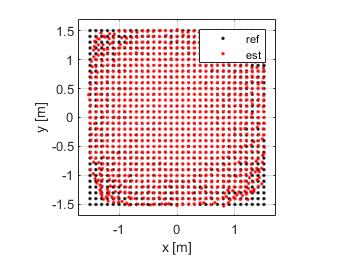

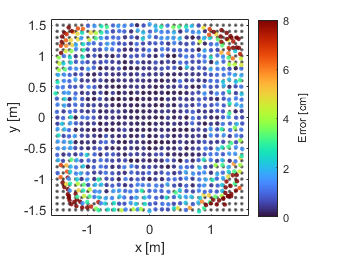

run('show_metrics.m');